# Sync the data between IMU and MC system

## Purpose of file

- Sync the time between the IMU measurements and the MC measurements, that is, estimate the time-shift. 

- FInd the coarse and fine rotation between the twos.

- The time shift is estimated by estimating the angular velocities from the rotation matrices from the MC systems and compare with the angular velocities by the gyroscopes. If they are not aligned, one should compare the norm of the angular velocities, but the coarse alignment was sufficient to get the rotation around the x-axis. The the x component is only compared. Then time shift IMU x-component of omega and sum the squared differences. 

- A fine alignment is also performed by comparing the direction of gravity. This is not so important since this misalignment will be incorporated into the $R$ matrix in the filter. We will not compare rotation matrices only positions.

## Load Data


% Estimate bias from stationary phase.
% FIG_SIZE = [0,0,800*1.5,500*1.5]

normalize_norm_v = @(x) x ./ norm_time(x);


### Load MC data

serie = 2;
exp = 2; 

% Load MC data 
% Load MC data 
pathScript = fileparts(matlab.desktop.editor.getActiveFilename)

pathScript = '/home/hakcar/phd/Array-INS-2/code/experiments/liu/serie-2/exp2'



file_mc  =sprintf("imu-%d-000%d.mat", serie, exp);
load(fullfile(pathScript,"raw_data","mc",file_mc));

% Load the data 
newStr = sprintf("imu_%d_000%d", serie, exp);
data_mc = eval(newStr);

### Load IMU data

data_IMU = load(fullfile(pathScript,"raw_data","imu","data_same_frame.mat"));

## Prepare data

N_sens = size(data_IMU.inertial_data_double_rot,1)

N_sens = 192

inds_tot = reshape(1:N_sens,6,[]);
N_imu = size(inds_tot,2);
inds_acc = reshape(inds_tot(1:3,:),[],1);
inds_gyro = reshape(inds_tot(4:6,:),[],1);
data_IMU.gyro = deg2rad(data_IMU.inertial_data_double_rot(inds_gyro,:));
data_IMU.acc = data_IMU.inertial_data_double_rot(inds_acc,:);
data_IMU.time = data_IMU.time_stamp_corr - data_IMU.time_stamp_corr(1);
data_IMU.acc

ans =    -0.4932   -0.4884   -0.5171   -0.5028   -0.4788   -0.4932   -0.4405   -0.4980   -0.4549   -0.4022   -0.5028   -0.4405   -0.4549   -0.3974   -0.4405   -0.5076   -0.4693   -0.4549   -0.4693   -0.4932   -0.4453   -0.4357   -0.4310   -0.4741   -0.4453   -0.4501   -0.4022   -0.5124   -0.4980   -0.5267   -0.5028   -0.5124   -0.5076   -0.4501   -0.4741   -0.4788   -0.5411   -0.4788   -0.4501   -0.4549   -0.4645   -0.4693   -0.4693   -0.5124   -0.5267   -0.4453   -0.5124   -0.5363   -0.4597   -0.4741
   -0.1006   -0.1197   -0.1963   -0.1484   -0.1628   -0.1628   -0.1628   -0.1724   -0.1484   -0.1389   -0.1820   -0.1149   -0.1580   -0.1437   -0.1484   -0.1484   -0.1293   -0.1820   -0.1820   -0.1724   -0.1053   -0.1389   -0.1628   -0.2346   -0.1867   -0.1341   -0.1724   -0.1245   -0.1915   -0.1293   -0.1580   -0.1963   -0.1963   -0.0814   -0.1437   -0.1915   -0.1915   -0.2155   -0.1915   -0.1867   -0.2011   -0.1580   -0.1484   -0.1628   -0.1293   -0.1197   -0.1628   -0.1628   -0.1820   

R_imu2rig_coarse = [ 
    0   -1  0;
    -1  0  0;
    0  0 -1];

data_IMU_mc_frame = struct;
R_imu2rig_coarse

R_imu2rig_coarse =      0    -1     0
    -1     0     0
     0     0    -1


% First around z, then around y, then around x
eul2rotm(deg2rad([-90 0 180]))

ans =     0.0000   -1.0000   -0.0000
   -1.0000   -0.0000   -0.0000
         0    0.0000   -1.0000


R_imu2rig_coarse - eul2rotm(deg2rad([-90 0 180]))

ans = 	1.0e+-15 *

   -0.0612         0    0.1225
         0    0.0612    0.0000
         0   -0.1225         0


data_IMU_mc_frame.r0 = R_imu2rig_coarse*data_IMU.r0

data_IMU_mc_frame = struct with fields:
    r0: [3×32 double]


data_IMU.r0*1e3

ans =    -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500
    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500
    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000


data_IMU_mc_frame.r0*1e3

ans =    -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500
    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500
   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000


R_imu2rig_coarse_tot = kron(eye(N_imu), R_imu2rig_coarse);
data_IMU_mc_frame.acc = R_imu2rig_coarse_tot*data_IMU.acc;
data_IMU_mc_frame.gyro = R_imu2rig_coarse_tot*data_IMU.gyro;
data_IMU_mc_frame.time = data_IMU.time;
data_IMU_mc_frame.Ts = data_IMU.Ts;
data_IMU_mc_frame.Fs = data_IMU.Fs;
data_IMU_mc_frame.mean_gyro = triad_mean(data_IMU_mc_frame.gyro);
data_IMU_mc_frame.mean_acc = triad_mean(data_IMU_mc_frame.acc);
% assert(all(data_R0_t_shift.R_imu2rig_coarse == eul2rotm(deg2rad([-90 0 180])), "all"))

#### Check MC Data

There are some missing samples in the MC data

p_mm = squeeze(data_mc.RigidBodies.Positions); % Positions in mm

bad_points = logical(any(isnan(p_mm)));
good_points = ~bad_points;

p_tot = p_mm/1000;
p = p_tot(:,good_points);
t_tot = ((data_mc.StartFrame:data_mc.Frames) - 1)/data_mc.FrameRate;
t = t_tot(good_points);


## Check Time 

#### Missing samples in the MC system

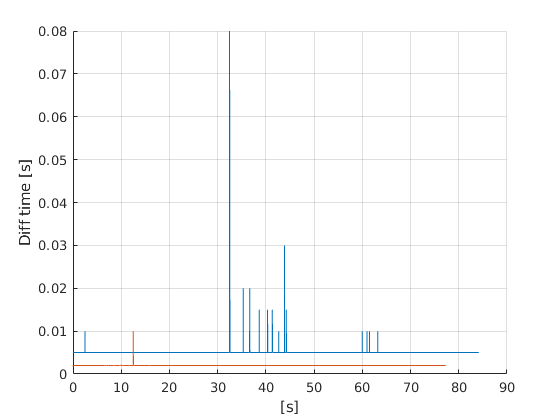

figure(); hold on
plot(t(1:end-1), diff(t), 'DisplayName',"Motion Capture")
plot(data_IMU.time(1:end-1),diff(data_IMU.time),'DisplayName',"IMU")
xlabel("[s]")
ylabel("Diff time [s]")
grid on

Some missing samples.

#### 3D plot of trajectory MC system

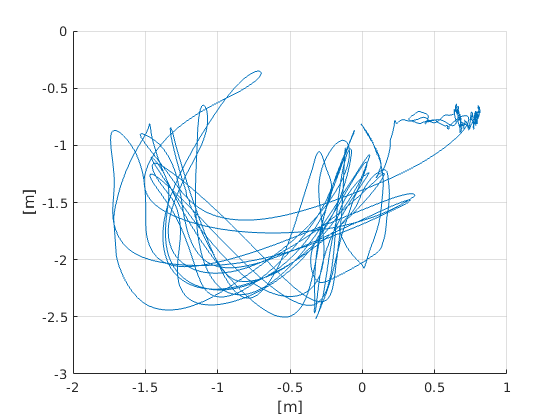

figure(); clf; hold on
plot3(p(1,:),p(2,:), p(3,:))

grid on

xlabel("[m]")
ylabel("[m]")

### Check position in regular 2D plot

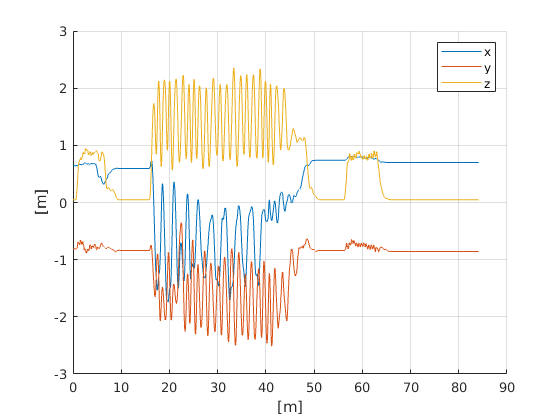

dirs = ["x","y","z"];
figure(); clf; hold on
for i =1:3
    plot(t, p(i,:),"DisplayName",dirs(i))
end

grid on
legend()
xlabel("[m]")
ylabel("[m]")

#### Rig rotation matrix

The rotation matrix is from local to global, that is body to global 

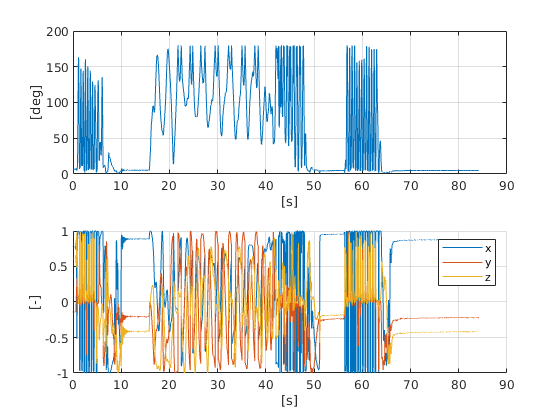

R_nb_rig_tot = squeeze(data_mc.RigidBodies.Rotations); % Rotation matrix
R_nb_rig = R_nb_rig_tot(:,good_points); % Take away nans 
R_nb_rig_3x3 = reshape(R_nb_rig,3,3,[]);
R_bn_rig_3x3 = zeros(size(R_nb_rig_3x3));

for n = 1:size(R_nb_rig_3x3,3)
    R_bn_rig_3x3(:,:,n) = R_nb_rig_3x3(:,:,n)';
end

figure(); hold on
ax = zeros(2,1);

axang = rotm2axang(R_nb_rig_3x3);
ax(1) = subplot(2,1,1);


plot(t, rad2deg(axang(:,4)))
% set(gca, "YScale", "log")
grid on
xlabel("[s]")
ylabel("[deg]")


ax(2) = subplot(2,1,2); hold on
for i = 1:3
    plot(t, axang(:,i))
end
grid on
legend("x","y","z")
xlabel("[s]")
ylabel("[-]")


% linkaxes(ax, "x");

## Estimate angular velocity from MC rotation matrices 

Use a forward differencing scheme.

w_nb_hat =  R2w_central_diff(R_nb_rig_3x3, t)

w_nb_hat =        NaN    0.0218    0.0646   -0.0257   -0.0380    0.0045   -0.0141   -0.0659   -0.0433    0.0298    0.0328   -0.0271    0.0188   -0.0180    0.0083    0.0041   -0.0413    0.0760   -0.0094   -0.0515    0.0277    0.0259   -0.0457    0.0103    0.0062   -0.0156    0.0145   -0.0127   -0.0309   -0.0126    0.0203   -0.0046   -0.0082    0.0281    0.0316    0.0094   -0.0143   -0.0234    0.0094    0.0264   -0.0065   -0.0080   -0.0038   -0.0087    0.0030    0.0214   -0.0147   -0.0487    0.0283   -0.0068
       NaN   -0.0788   -0.0002   -0.0575   -0.0411    0.0127    0.0286    0.0194    0.0373    0.0150   -0.0052   -0.0024    0.0029   -0.0098   -0.0166   -0.0079    0.0066    0.0048    0.0158    0.0056   -0.0148   -0.0034    0.0316   -0.0069   -0.0181    0.0207   -0.0093   -0.0031   -0.0056    0.0074    0.0140   -0.0091   -0.0307   -0.0140    0.0342    0.0154   -0.0338    0.0001    0.0232    0.0217   -0.0152   -0.0146    0.0105    0.0087    0.0205    0.0005   -0.0008   -0.0340   -0.01

% Set the neighbours
w_nb_hat(:,1) = w_nb_hat(:,2);
w_nb_hat(:,end) = w_nb_hat(:,end-1);
% zeros(3,length(t));
% 
% for k = 2:length(t)
%     dt = t(k) - t(k-1);
%     w_nb_hat(:,k) = logSO3(R_nb_rig_3x3(:,:,k-1)'*R_nb_rig_3x3(:,:,k))/dt;
% end


## Rotate IMU to IMU-rig coarse

Found this matrix by looking at the photos.

### Plot angular velocity components

figure()
ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU_mc_frame.time, data_IMU_mc_frame.mean_gyro(i,:), "DisplayName","IMU")
    grid on 
    legend
end
linkaxes(ax, 'x'); clf reset;

Looks like they are the same.

### Plot angular velocity norm

Compare the norm instead, not depedent on the orientation of the rig

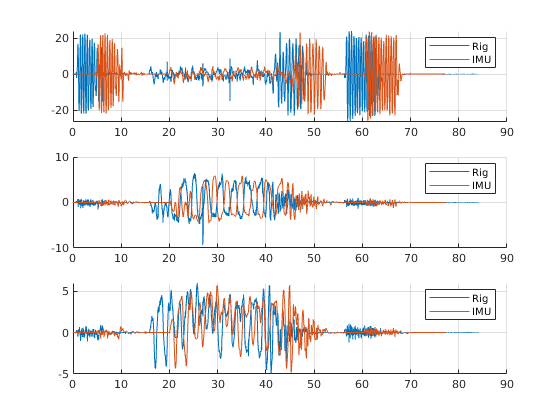

figure()

ax = zeros(3,1);
hold on
plot(t, norm_time(w_nb_hat), "DisplayName","Rig")
plot(data_IMU.time, norm_time(data_IMU_mc_frame.mean_gyro), "DisplayName","IMU")
grid on 
legend

The normed signal of the angular velocity does not look very smooth, that can be explained by the $y$ and $z$ components that are quire noisy. It is then better to just use $x$ component.

## Estimate rotation matrix between IMU and rig using gravity (Fine alignment)

The body frames of the IMU and the rig is not perfectly aligned. 

Downward in bodyframe should point in the direction of gravity in body frame coordinates.

Downward of the navigation frame is the third column of the R_bn matrix, the rotation matrix from navigation frame to body frame.

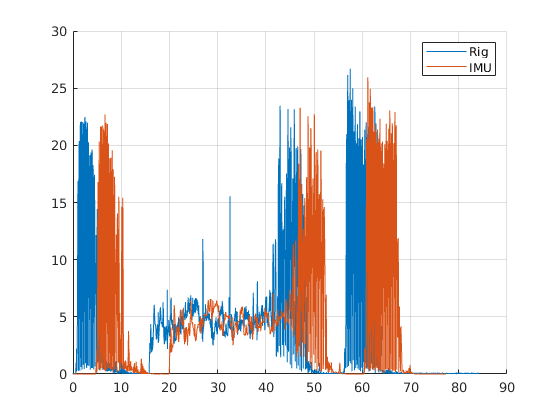

rig_unit_tot = reshape(R_bn_rig_3x3(:,3,:),3,[])
imu_unit_tot = normalize_norm_v(data_IMU_mc_frame.mean_acc)

mask_stationary_rig = t <= 0.5;
mask_stationary_IMU = data_IMU_mc_frame.time <= 4;

figure(); 

rig_unit_tot =     0.0187    0.0198    0.0195    0.0198    0.0201    0.0202    0.0199    0.0199    0.0198    0.0196    0.0196    0.0196    0.0196    0.0196    0.0197    0.0197    0.0198    0.0197    0.0198    0.0195    0.0197    0.0197    0.0197    0.0194    0.0198    0.0195    0.0196    0.0196    0.0196    0.0197    0.0196    0.0196    0.0197    0.0199    0.0198    0.0195    0.0196    0.0199    0.0196    0.0196    0.0194    0.0198    0.0196    0.0197    0.0195    0.0195    0.0195    0.0195    0.0198    0.0196
    0.0899    0.0896    0.0902    0.0902    0.0899    0.0898    0.0899    0.0897    0.0893    0.0893    0.0896    0.0896    0.0893    0.0898    0.0891    0.0899    0.0892    0.0894    0.0899    0.0893    0.0894    0.0896    0.0897    0.0892    0.0898    0.0892    0.0896    0.0894    0.0895    0.0891    0.0894    0.0893    0.0893    0.0892    0.0896    0.0895    0.0897    0.0894    0.0895    0.0895    0.0897    0.0894    0.0897    0.0894    0.0896    0.0894    0.0898    0.0892    

for i = 1:3

imu_unit_tot =     0.0002    0.0007    0.0018    0.0010    0.0021    0.0009    0.0005    0.0027    0.0016    0.0014    0.0017    0.0021    0.0017    0.0024    0.0009    0.0022    0.0016    0.0025    0.0018    0.0014    0.0017    0.0022    0.0018    0.0035    0.0004    0.0013    0.0018    0.0006    0.0019    0.0012    0.0012    0.0017    0.0002    0.0007    0.0028    0.0003    0.0014    0.0015    0.0016    0.0015    0.0013    0.0020    0.0026    0.0013    0.0014    0.0018    0.0019    0.0024    0.0032    0.0017
    0.0441    0.0435    0.0431    0.0438    0.0443    0.0433    0.0435    0.0448    0.0439    0.0441    0.0436    0.0433    0.0438    0.0446    0.0434    0.0453    0.0441    0.0448    0.0438    0.0441    0.0449    0.0437    0.0442    0.0434    0.0441    0.0430    0.0436    0.0433    0.0442    0.0430    0.0443    0.0451    0.0446    0.0437    0.0440    0.0457    0.0452    0.0448    0.0457    0.0430    0.0430    0.0438    0.0435    0.0432    0.0435    0.0438    0.0442    0.0441    

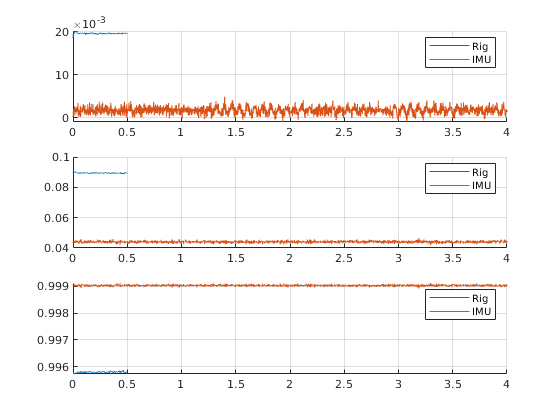

    subplot(3,1,i); hold on 
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot(i,mask_stationary_IMU), "DisplayName","IMU")
    grid on 
    legend
end

### Find angle difference 

[R_stationary_rig_mean, e_R] = average_rotation(R_bn_rig_3x3(:,:,mask_stationary_rig), 100, 1e-12)

1/100: tol: 1.251e-03 / 1.000e-12
2/100: tol: 1.437e-11 / 1.000e-12
3/100: tol: 4.629e-18 / 1.000e-12


R_stationary_rig_mean =     0.9973    0.0708    0.0196
   -0.0723    0.9934    0.0895
   -0.0132   -0.0906    0.9958


e_R =    -0.0004   -0.0001   -0.0007   -0.0008   -0.0005   -0.0004   -0.0005   -0.0002    0.0002    0.0002   -0.0001   -0.0001    0.0002   -0.0003    0.0003   -0.0004    0.0003    0.0000   -0.0005    0.0001    0.0000   -0.0002   -0.0002    0.0003   -0.0003    0.0002   -0.0002    0.0001   -0.0000    0.0004    0.0001    0.0002    0.0001    0.0003   -0.0002   -0.0000   -0.0002    0.0001   -0.0000    0.0000   -0.0003    0.0001   -0.0002    0.0001   -0.0001    0.0001   -0.0003    0.0002    0.0002   -0.0001
   -0.0010    0.0002   -0.0002    0.0001    0.0004    0.0005    0.0003    0.0003    0.0002   -0.0001   -0.0000   -0.0001    0.0000   -0.0001    0.0001    0.0001    0.0002    0.0000    0.0001   -0.0001    0.0001    0.0000    0.0001   -0.0003    0.0001   -0.0001   -0.0001   -0.0000   -0.0000    0.0001   -0.0001   -0.0001    0.0000    0.0002    0.0001   -0.0001   -0.0000    0.0002   -0.0000   -0.0000   -0.0002    0.0001   -0.0001    0.0000   -0.0002   -0.0002   -0.0002   -0.0002    0.0002   

det(R_stationary_rig_mean)

ans = 1.0000

R_stationary_rig_mean'*R_stationary_rig_mean

ans =     1.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000


dir_rig = R_stationary_rig_mean(:,3)

dir_rig =     0.0196
    0.0895
    0.9958


norm(dir_rig)

ans = 1.0000

dir_imu = normalize_norm_v(mean(data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU),2))

dir_imu =     0.0018
    0.0440
    0.9990



norm(dir_imu)

ans = 1

acosd(dot(dir_rig,dir_imu))

ans = 2.8032

3 degress difference. Level spirit sensitivity is 10mm/m

atand(10e-3/1)

ans = 0.5729

Which is 0.5 deg. Meaning the difference is above what the level spirit can measure. 

Rotationmatrix between unit vectors, from 

R_rig_coarse2rig_fine = rotationMatrixFromTwoUnitVectors(dir_imu, dir_rig)

R_rig_coarse2rig_fine =     0.9998    0.0003    0.0179
   -0.0011    0.9990    0.0455
   -0.0179   -0.0455    0.9988


It is almost the identiy matrix

rad2deg(my_rotm2eul(R_rig_coarse2rig_fine))

ans =    -2.6097
    1.0228
   -0.0638



det(R_rig_coarse2rig_fine)

ans = 1.0000

R_rig_coarse2rig_fine'*R_rig_coarse2rig_fine

ans =     1.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


R_rig_coarse2rig_fine*dir_imu

ans =     0.0196
    0.0895
    0.9958


dir_rig

dir_rig =     0.0196
    0.0895
    0.9958


norm(R_rig_coarse2rig_fine*dir_imu - dir_rig)

ans = 6.8390e-11

How many degress does the rotation matrix rotate.

rad2deg(norm(logSO3(R_rig_coarse2rig_fine)))

ans = 2.8032

Check that the rotation matrix is reasonable 

imu_unit_tot_2 = normalize_norm_v(R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU))

imu_unit_tot_2 =     0.0181    0.0186    0.0197    0.0189    0.0200    0.0188    0.0184    0.0206    0.0195    0.0192    0.0196    0.0200    0.0196    0.0203    0.0187    0.0201    0.0195    0.0204    0.0197    0.0193    0.0196    0.0201    0.0197    0.0214    0.0182    0.0192    0.0197    0.0185    0.0198    0.0191    0.0191    0.0196    0.0181    0.0186    0.0207    0.0182    0.0192    0.0193    0.0195    0.0194    0.0192    0.0198    0.0205    0.0192    0.0193    0.0196    0.0197    0.0203    0.0211    0.0196
    0.0895    0.0889    0.0885    0.0892    0.0897    0.0887    0.0889    0.0903    0.0893    0.0896    0.0891    0.0887    0.0892    0.0900    0.0889    0.0908    0.0896    0.0902    0.0893    0.0895    0.0903    0.0892    0.0896    0.0889    0.0895    0.0885    0.0890    0.0887    0.0896    0.0884    0.0897    0.0905    0.0901    0.0891    0.0894    0.0911    0.0906    0.0902    0.0911    0.0884    0.0885    0.0893    0.0889    0.0886    0.0889    0.0892    0.0896    0.0895  

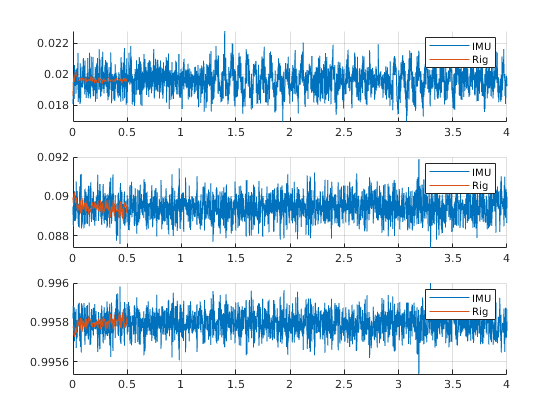

figure(); 
for i = 1:3
    subplot(3,1,i); hold on 
    
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot_2(i,mask_stationary_IMU), "DisplayName","IMU")
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    grid on 
    legend
end

Check that gyro gives reasonable reasults as well

phase_roll_1 = data_IMU.start_and_stop(1,2):data_IMU.start_and_stop(2,1);

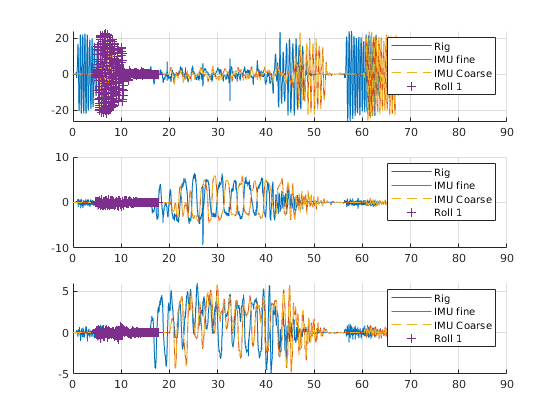

gyro_2 = R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_gyro;
figure()
ax = zeros(3,1);

for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU.time, gyro_2(i,:) , "DisplayName","IMU fine ")
    plot(data_IMU.time, data_IMU_mc_frame.mean_gyro(i,:) ,"--", "DisplayName","IMU Coarse")
    plot(data_IMU.time(phase_roll_1), data_IMU_mc_frame.mean_gyro(i,phase_roll_1) ,"+", "DisplayName","Roll 1", "MarkerIndices",1:10:length(phase_roll_1))
    grid on 
    legend
end

The fine rotation does not matter.

#### Rotatate measurements fine alignment

## Grid search time sync

Extract the phase time sync sequence

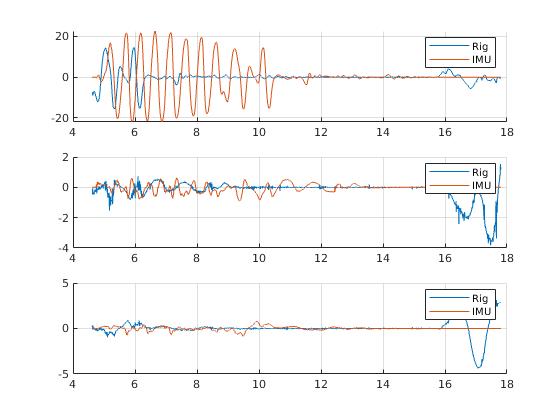


figure
ax = zeros(3,1);
time_IMU = data_IMU.time(phase_roll_1);
mask_time_rig = logical( (t >= time_IMU(1)) .* (t <= time_IMU(end)));
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t(mask_time_rig), w_nb_hat(i,mask_time_rig), "DisplayName","Rig")
    plot(time_IMU, data_IMU_mc_frame.mean_gyro(i,phase_roll_1), "DisplayName","IMU")
    grid on 
    legend
end
slice_time_sync_1_phase = phase_roll_1
% linkaxes(ax);

Interpolate rig w to IMU angular velocity. Use the x direction.

y_interp = data_IMU_mc_frame.mean_gyro(1,slice_time_sync_1_phase);

slice_time_sync_1_phase =         2308        2309        2310        2311        2312        2313        2314        2315        2316        2317        2318        2319        2320        2321        2322        2323        2324        2325        2326        2327        2328        2329        2330        2331        2332        2333        2334        2335        2336        2337        2338        2339        2340        2341        2342        2343        2344        2345        2346        2347        2348        2349        2350        2351        2352        2353        2354        2355        2356        2357


t_interp = time_IMU;
length(t_interp)

% cubic spline iterpolation 
f = @(t_shift) interp1( t, w_nb_hat(1,:),  t_interp - t_shift, 'pchip');
f(0)

cost = @(t_shift) sum((y_interp - f(t_shift)).^2);

ans = 6595

cost(0)

Ocular inspection of coarse time shift 

t_shift_coarse = 4


ans =    -8.1432   -8.2146   -8.2810   -8.3169   -8.2958   -8.2278   -8.0947   -7.6856   -7.3792   -7.6071   -8.1570   -8.5750   -8.9313   -9.1284   -8.8573   -8.2792   -8.0350   -7.9667   -7.9166   -7.8691   -7.8252   -7.7481   -7.5833   -7.4121   -7.2771   -7.1633   -7.1396   -7.1594   -7.1755   -7.1446   -7.0776   -7.0448   -7.0300   -7.0231   -7.0344   -7.0572   -7.0560   -6.9911   -6.9381   -6.9469   -6.9770   -7.0264   -7.1467   -7.2807   -7.3873   -7.4829   -7.5377   -7.5635   -7.5939   -7.6672


grid_search = t_shift_coarse + (-1:0.01:1);
cost_grid = arrayfun(cost, grid_search);


ans = 6.0459e+05

options = optimset('Display','iter','TolX', 1e-12);
t_shift_opt = fminbnd(cost,grid_search(1),grid_search(end),options);


t_shift_coarse = 4

data_IMU.time_shifted = data_IMU.time - t_shift_opt;
figure(); clf;
plot(grid_search, cost_grid, "-x")
hold on 
yLim = ylim;
plot(t_shift_opt*ones(1,2), yLim, "-r")

 
 Func-count     x          f(x)         Procedure
    1        3.76393       606385        initial
    2        4.23607       326497        golden
    3        4.52786  1.09193e+06        golden
    4        4.07041       693441        parabolic
    5        4.34752  1.49359e+06        golden
    6        4.17279      409.267        golden
    7        4.13369       113502        golden
    8        4.17164      156.088        parabolic
    9        4.17088      112.099        parabolic
   10        4.17092      111.953        parabolic
   11        4.17092      111.953        parabolic
   12        4.17092      111.953        parabolic
   13        4.17092      111.953        parabolic
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-12 



ylim(yLim);

### Ensure time shift is ok

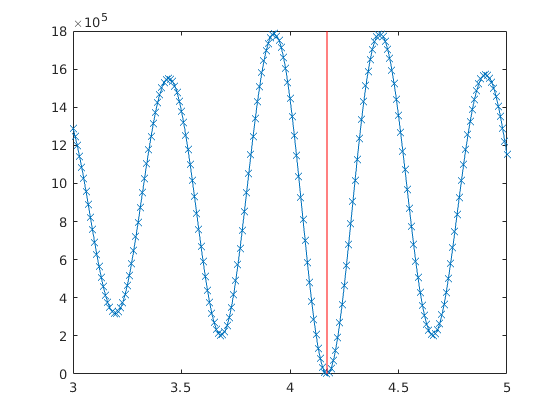

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;
    plot(t, rad2deg(w_nb_hat(i,:))', 'DisplayName', "MC")


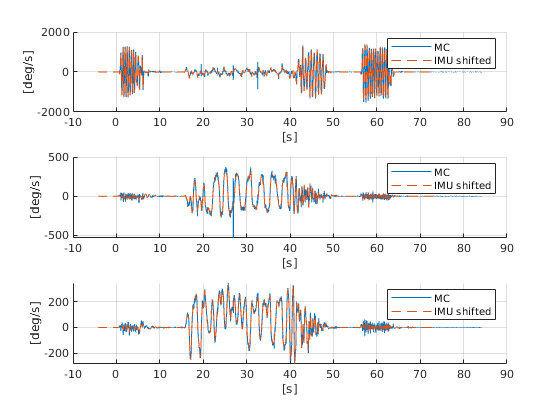

    % plot(data_IMU.time, rad2deg(data_IMU_gyro.gyro_wls_wo_bias_rig_frame_fine(i,:)),'DisplayName','IMU')
    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"--",'DisplayName','IMU shifted')
    
    % yLim = ylim; 
    % X = [data_IMU.start_and_stop(1,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(1,1)];
    % Y = [yLim(2) yLim(2) yLim(1) yLim(1)];
    % fill(data_IMU.time_stamp_corr(X), Y, "b", "FaceAlpha", 0.2);
    % ylim(yLim);
    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
end

figure(); hold on 
plot(data_IMU.time_shifted, "DisplayName","Shifted time")
plot(data_IMU.time,"--", "DisplayName","Original Time")
plot(t, "DisplayName","Rig Time")
legend
grid on 


xlim([0 391])
% ylim([-1.35 0.71])

## Find release times

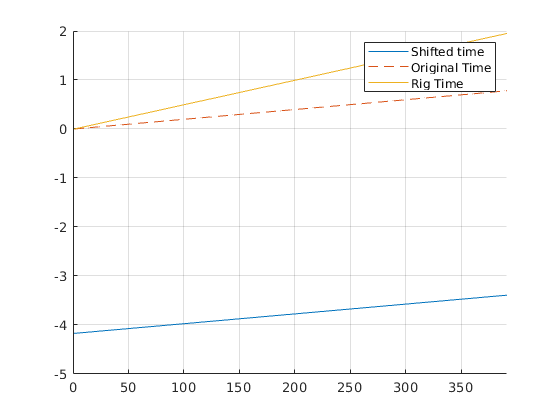



release_times_roll_2 = 56.5 + (0:19)*0.1
release_times_roll_2_end = release_times_roll_2 + 5;

w_roll_2_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2)';
w_roll_2_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2_end)';



release_times_middle = 16.5 + (0:19)*1.4
release_times_middle_end = release_times_middle + 5;

w_middle_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle)';

release_times_roll_2 =    56.5000   56.6000   56.7000   56.8000   56.9000   57.0000   57.1000   57.2000   57.3000   57.4000   57.5000   57.6000   57.7000   57.8000   57.9000   58.0000   58.1000   58.2000   58.3000   58.4000


w_middle_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle_end)';

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;

release_times_middle =    16.5000   17.9000   19.3000   20.7000   22.1000   23.5000   24.9000   26.3000   27.7000   29.1000   30.5000   31.9000   33.3000   34.7000   36.1000   37.5000   38.9000   40.3000   41.7000   43.1000


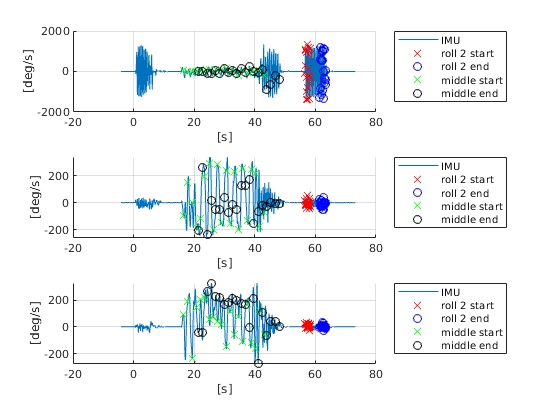


    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"-",'DisplayName','IMU')
    plot(release_times_roll_2, rad2deg(w_roll_2_start(i,:)),"rx",'DisplayName','roll 2 start')
    plot(release_times_roll_2_end, rad2deg(w_roll_2_end(i,:)),"bo",'DisplayName','roll 2 end')
    
    plot(release_times_middle, rad2deg(w_middle_start(i,:)),"gx",'DisplayName','middle start')
    plot(release_times_middle_end, rad2deg(w_middle_end(i,:)),"ko",'DisplayName','middle end')

    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
    legend("Location","bestoutside")
end

## Save Joint data

mkdir(fullfile(pathScript,"estimated_parameters"))

save(fullfile(pathScript,"estimated_parameters","R0_and_tshift.mat"), "R_imu2rig_coarse","t_shift_opt", "release_times_middle", "release_times_roll_2");

% save(fullfile(pathScript,"data_processed","data_initial_values.mat"),"-struct", "data_initial_values");

## Conclusions 

- Coarse alignment is only off by 3 degrees.

- The time-sync was performed on the fine aligned gyroscope wls data, but it is expected that this does not matter if the time-shift estimation was done on the coarse aligned data.

- The time-shift was estimation was done using linearly interpolated data and grid-search. 